Deci.Step =5;
Deci.SubjectList = 'all';

Deci.Analysis.Conditions = {[399 550 110 201] [ 399 551 110 201] [399 552 110 201] [399 553 110 201] [399 554 110 201] ...
                           [399 550 111 201] [399 551 111 201] [399 552 111 201] [399 553 111 201] [399 554 111 201] ...
                           ... %%[399 550 201] [399 551 201] [399 552 201] [399 553 201] [399 554 201] ...
                           [399 550 160 201] [399 551 160 201] [399 552 160 201] [399 553 160 201] [399 554 160 201] ...
                           [399 550 161 201] [399 551 161 201] [399 552 161 201] [399 553 161 201] [399 554 161 201]};
                          
Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';
Deci.Plot.Behv.Static = [399];

Deci.DT.Type       = 'LCM';             
    Deci.DT.Starts     = {10 11};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {200 201 202};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[10 11] [20:27] [399] [211:218] [221:228] [110:111] [141:148] [151:158] [160:161] [200 201 202]};   
    Deci.DT.Locks      = [399 499];
    Deci.DT.Toi        = [-2 3]; 

%% Irrelevant but necessary
Deci.Plot.Behv.Acc.Figure = [false false false false false];
Deci.Plot.Behv.Acc.Total = {{[1 6] [2 7] [3 8] [4 9] [5 10]}};%[11 16] [12 17] [13 18] [14 19] [15 20]}};
Deci.Plot.Behv.Acc.Subtotal = {{[1] [2] [3] [4] [5]}};% [11] [12] [13] [14] [15]}};
Deci.Plot.Behv.Acc.Title = {'All Trials Percent'};% 'PvST all trials'};
Deci.Plot.Behv.Acc.Subtitle = {{'0-Diff cor' '1-Diff cor' '2-Diff cor' '3-Diff cor' '4-Diff cor' }};
                   %'0-diff PvST cor' '1-diff PvST cor' '2-diff PvST cor' '3-diff PvST cor' '4-diff PvST cor'... %'0-Diff incor' '1-Diff incor' '2-Diff incor' '3-Diff incor' '4-Diff incor' ...
                   %'0-diff PvST incor' '1-diff PvST incor' '2-diff PvST incor' '3-diff PvST incor' '4-diff PvST incor'}};
 
Deci.Plot.Behv.Acc.Block = [21:27];
Deci.Plot.Behv.Acc.Collapse.Trial =true;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = true;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;



%% RT Loop
% name = strsplit(Deci.Folder.Version,'\');
Deci.Plot.Behv.RT.Figure = [true];
Deci.Plot.Behv.RT.Draw = {{[1:5] [6:10] [11:15] [16:20]}}; 
% Deci.Plot.Behv.RT.Title = {[name(end)+'_Title']};
% Deci.Plot.Behv.RT.Subtitle = {[name{end}+'_110'],[name{end}+'_111'],[name{end}+'_all'],[name{end}+'_160'],[name{end}+'_161']};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [550:554];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = false;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans'

Deci = struct with fields:
       Analysis: [1×1 struct]
           Step: 5
    SubjectList: 'all'
           Plot: [1×1 struct]
             DT: [1×1 struct]
            Run: [1×1 struct]
         Folder: [1×1 struct]
           sort: [550 551 552 553 554]


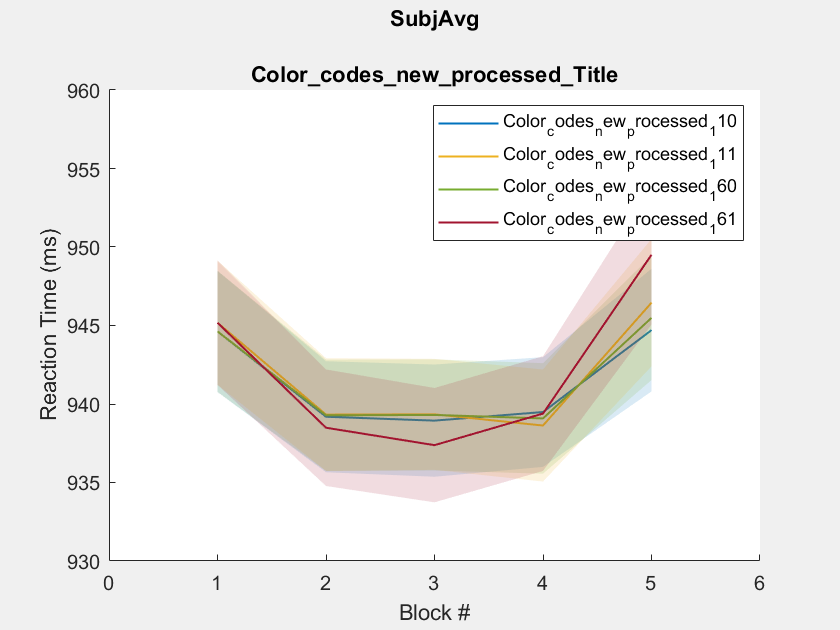

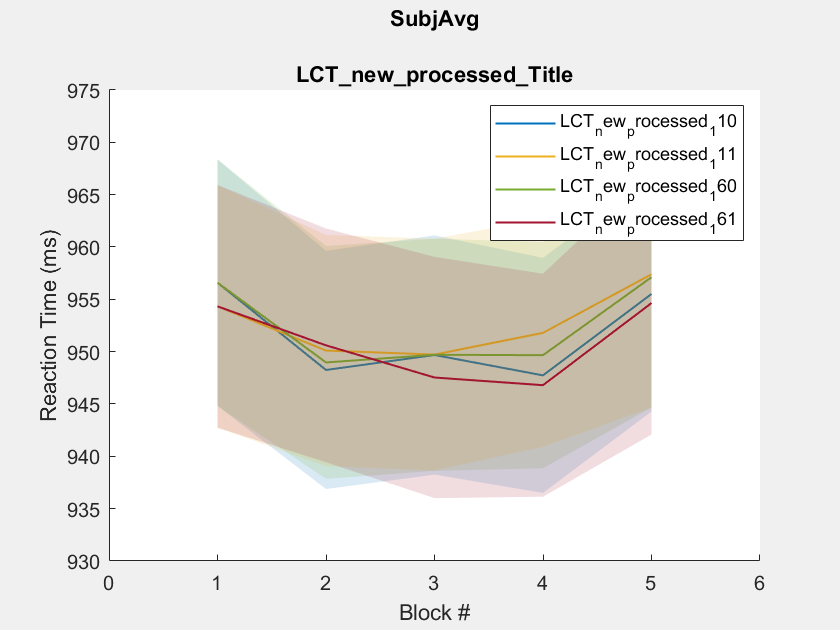

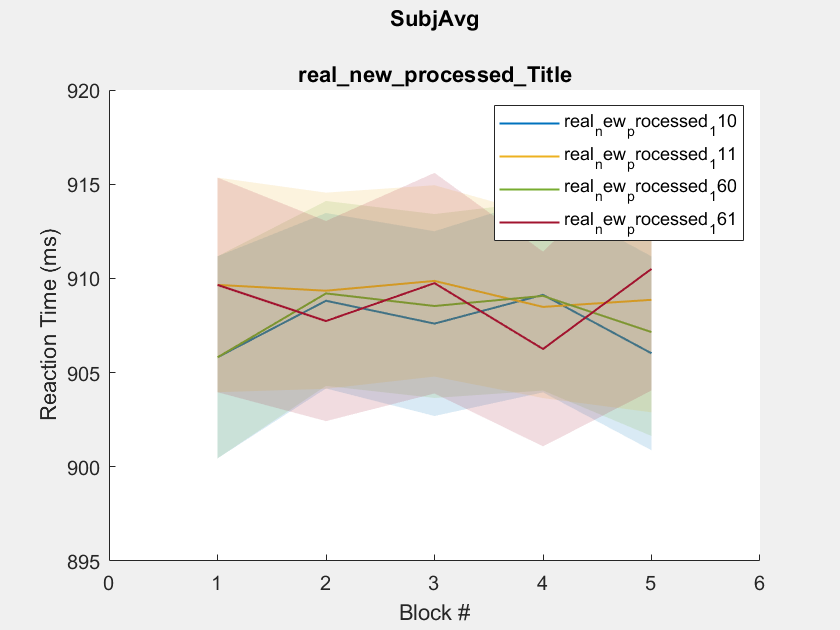



Deci.Run.Behavior = true;
Deci.Run.Freq =false;
Deci.Run.ERP =false;
Deci.Run.CFC = false;

feedmedata = '\\128.197.62.203\Public\Backup\Public\Dropbox\Shrey\data\feedmedata';
% piles = cleandir(Deci.Folder.Versionbase)
piles = {'Color_codes','LCT','real'};
for i = 1:length(piles)
    
    Deci.Folder.Raw = strcat(feedmedata,'\',piles{i},'_new');
    Deci.Folder.Version = strcat(feedmedata,'\processed\', piles{i},'_new_processed');
        
    name = strsplit(Deci.Folder.Version,'\');
    
    Deci.Plot.Behv.RT.Title = {{strcat(name{end},'_Title')}};
    Deci.Plot.Behv.RT.Subtitle = {{strcat(name{end},'_110'),strcat(name{end},'_111'),strcat(name{end},'_160'),strcat(name{end},'_161')}};
    Deci.sort = (550:554);
    Deci_Backend(Deci)
end